# Compile Figures for Synthetic Data

%%%%%%
%Script for compiling the figure generator
%%%%%%

clear all
close all


%What is your project name?
ProjFolder = 'CB_thawingdepth_disturbed_DOC/';

%do you want the figure saved?
printfig  = true;

%Where do you want to save files?
workdirfig_DOC = '/Users/cansu/Documents/GitHub/Permafrost_ERRA/datERRA/Thawing/CB_thawingdepth_disturbed_DOC/figures/DOC';
workdirfig_POC = '/Users/cansu/Documents/GitHub/Permafrost_ERRA/datERRA/Thawing/CB_thawingdepth_disturbed_DOC/figures/POC';
workdirfig_SSC = '/Users/cansu/Documents/GitHub/Permafrost_ERRA/datERRA/Thawing/CB_thawingdepth_disturbed_DOC/figures/SSC';

%Where is your data?
workdir = '/Users/cansu/Documents/GitHub/Permafrost_ERRA/datERRA/Thawing/CB_thawingdepth_disturbed_DOC/';



Lets plot the results

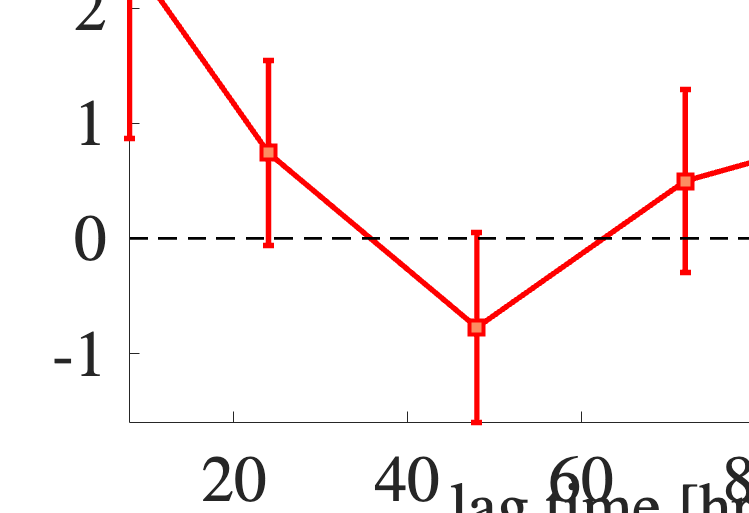

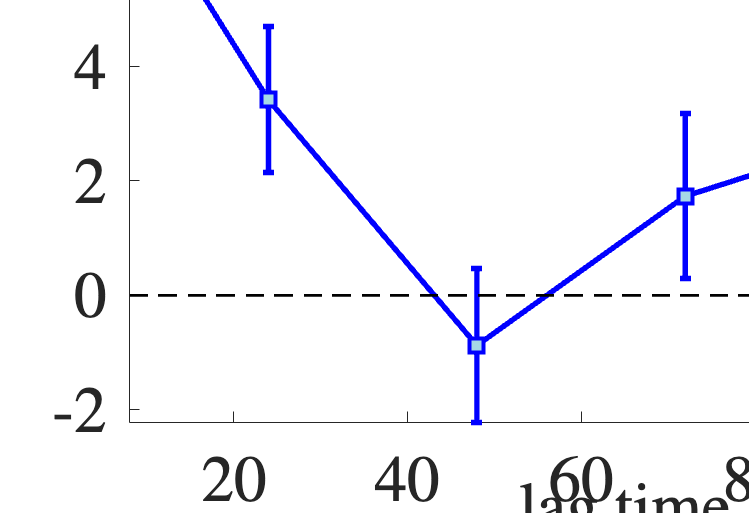

f4 =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [0.7000 12 9.3500 6.4000]
       Units: 'inches'

  Show all properties


% % %Plot time with discharge and precipitation. This function will change
% % %depending on data format. Please change this function accordingly
% % origdat=char(strcat(originaldata(1)));
% % f1 = figtQP_plot_UK(origdat,workdir,workdirfig,printfig)

cd(workdir)
nameplot = {'Rainfall - Carbon Runoff Response Distribution [$\frac{\mathrm{mg}}{\mathrm{mm}^4}$]', 'Thawing - Carbon Runoff Response Distribution [$\frac{\mathrm{mg}}{\mathrm{mm}^4}$]'};
colors_ = 1;

%Plot lagtime with RRD
str = {'Rresults/1hr_simple_DOC_RRD.txt'};
f4 = figtRRD_plot_dZ('Ptarmigan, Melville Island (NU) Disturbed; DOC',workdir,workdirfig_DOC,printfig,2,str,nameplot,colors_)

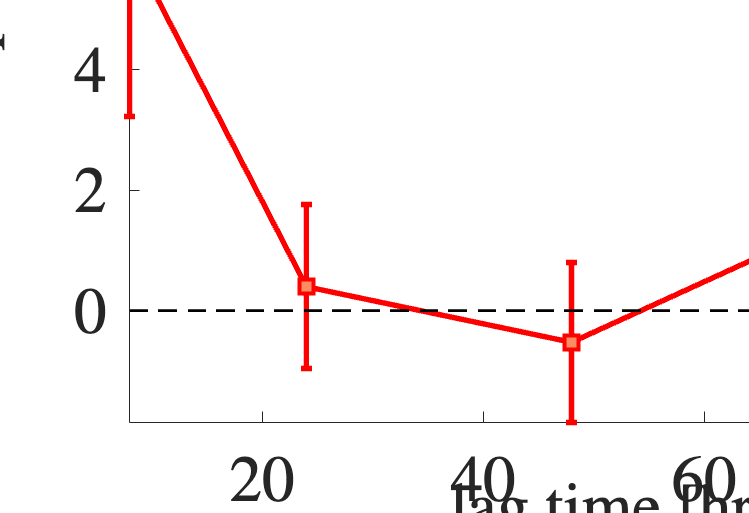

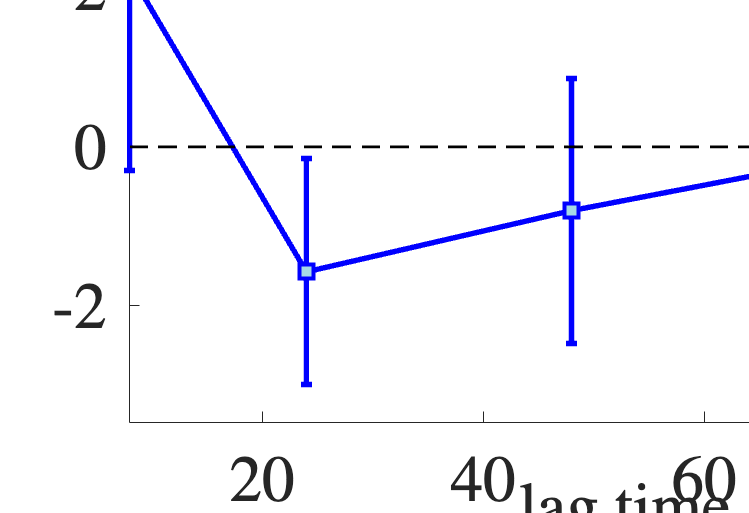

f4 =   Figure (3) with properties:

      Number: 3
        Name: ''
       Color: [1 1 1]
    Position: [0.7000 12 9.3500 6.4000]
       Units: 'inches'

  Show all properties



cd(workdir)
nameplot = {'Rainfall - Carbon Runoff Response Distribution [$\frac{\mathrm{mg}}{\mathrm{mm}^4}$]', 'Thawing - Carbon Runoff Response Distribution [$\frac{\mathrm{mg}}{\mathrm{mm}^4}$]'};
colors_ = 1;

%Plot lagtime with RRD
str = {'Rresults/1hr_simple_POC_RRD.txt'};
f4 = figtRRD_plot_dZ('Ptarmigan, Melville Island (NU) Disturbed; POC',workdir,workdirfig_POC,printfig,2,str,nameplot,colors_)


cd(workdir)
nameplot = {'Rainfall - Carbon Runoff Response Distribution [$\frac{\mathrm{mg}}{\mathrm{mm}^4}$]', 'Thawing - Carbon Runoff Response Distribution [$\frac{\mathrm{mg}}{\mathrm{mm}^4}$]'};
colors_ = 1;

%Plot lagtime with RRD
str = {'Rresults/1hr_simple_SSC_RRD.txt'};
f4 = figtRRD_plot_dZ('Ptarmigan, Melville Island (NU) Disturbed; SSC',workdir,workdirfig_SSC,printfig,2,str,nameplot,colors_)

Error using matlab.io.ImportOptions/readtable
Unable to find or open 'Rresults/1hr_simple_SSC_RRD.txt'. Check the path and filename or file permissions.

Error in figtRRD_plot_dZ (line 63)
dat = readtable(filename, opts);